clear
clc

% Die MATLAB Deep Learning Toolbox stellt einige Funktionen zum Arbeiten mit
% tiefen neuronalen Netzen zur Verfügung.

baseFolder = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt";
cd(baseFolder)

datenFolder = baseFolder + "\09_Trainingsdaten\AusgeschnittenFuerTraining\99_Trainingsdatensaetze\03_13Kat_Alle Schilder";

imdsSchilder = imageDatastore(datenFolder, ...
    "IncludeSubfolders", true, ...
    "LabelSource", "foldernames");

countEachLabel(imdsSchilder)

ans = 13×2 table
                  Label                   Count
    __________________________________    _____

    Achtung_Gefahrenstelle                 377 
    BilderOhneSchilder                     408 
    Durchfahrt_Verboten_Einbahnstrasse     509 
    Fussgaengerueberweg                    207 
    Geschwindigkeitsbegrenzung_100         427 
    Geschwindigkeitsbegrenzung_30          337 
    Geschwindigkeitsbegrenzung_50          315 
    Geschwindigkeitsbegrenzung_70          491 
    Geschwindigkeitsempfehlung_30          571 
    Geschwindigkeitsempfehlung_90          558 
    Stoppschild                            143 
    Verkehrsberuhigter_Bereich             220 
    Vorfahrt_Achten                        304 



numPerLabel = min(countEachLabel(imdsSchilder).Count);
allLabels = unique(imdsSchilder.Labels);
classNames = categories(imdsSchilder.Labels);

numRuns = 1;

% Ergebnisvariablen für Excel-Ausgabe
RunNr = zeros(numRuns,1);
TrainAccuracy = zeros(numRuns,1);
ValidationAccuracy = zeros(numRuns,1);
GesamtAccuracy = zeros(numRuns,1);
AnzahlFalschTrain = zeros(numRuns,1);
AnzahlFalschValidation = zeros(numRuns,1);
AnzahlFalschGesamt = zeros(numRuns,1);

for run = 1:numRuns

    fprintf("\n=====================================\n");
    fprintf("START LAUF %d von %d\n", run, numRuns);
    fprintf("=====================================\n");

    % Jeder Lauf bekommt anderen, aber reproduzierbaren Zufall
    rng(run, "twister")

    %% Balancing neu erzeugen
    balancedFiles = [];

    for i = 1:numel(allLabels)
        label = allLabels(i);

        idx = find(imdsSchilder.Labels == label);

        if numel(idx) >= numPerLabel
            selectedIdx = randsample(idx, numPerLabel);
            balancedFiles = [balancedFiles; imdsSchilder.Files(selectedIdx)];
        else
            warning("Label '%s' hat weniger als %d Bilder.", string(label), numPerLabel);
        end
    end

    % Neuen ImageDatastore mit ausgewählten Dateien erstellen
    balancedDS = imageDatastore(balancedFiles, ...
        'Labels', categorical(cellstr(extractBetween(balancedFiles, ...
        fullfile(datenFolder, '\'), filesep))));

    %% Train-/Validation-Split neu erzeugen
    [imdsTrain, imdsValidation] = splitEachLabel(balancedDS, 0.8, "randomized");
    miniBatchSize = 16;
    numTrainImages = numel(imdsTrain.Files);
    iterationsPerEpoch = ceil(numTrainImages / miniBatchSize);

    %% Netzwerk definieren
    % GAP-Variante
   layers = [
         imageInputLayer([48, 48, 3],"Name", "input","Normalization", "none")

        convolution2dLayer(3, 16,"Padding", "same",  "Name", "conv_1")
        reluLayer("Name", "relu_1")
        maxPooling2dLayer(2, "Stride", 2,"Name", "maxpool_1")
        
        convolution2dLayer(3, 32,"Padding", "same", "Name", "conv_2")
        reluLayer("Name", "relu_2")
        maxPooling2dLayer(2, "Stride", 2,  "Name", "maxpool_2")
        
        convolution2dLayer(3, 64,  "Padding", "same",  "Name", "conv_3")
        reluLayer("Name", "relu_3")
        
        convolution2dLayer(3, 64, "Padding", "same",   "Name", "conv_4")
        reluLayer("Name", "relu_4")
        
        convolution2dLayer(1, 13, "Name", "conv_out")
        globalAveragePooling2dLayer("Name", "gap")
        softmaxLayer("Name", "softmax")
    ];

    %% Augmented Datastores
    augTrain = augmentedImageDatastore([48 48 3], imdsTrain, ...
        'ColorPreprocessing', 'none', ...
        'OutputSizeMode', 'resize');

    augVal = augmentedImageDatastore([48 48 3], imdsValidation, ...
        'ColorPreprocessing', 'none', ...
        'OutputSizeMode', 'resize');

    aug2 = augmentedImageDatastore([48 48 3], imdsSchilder, ...
        'ColorPreprocessing', 'none', ...
        'OutputSizeMode', 'resize');

    %% Trainingsparameter
        %      'LearnRateSchedule', 'piecewise', ...
        % 'LearnRateDropFactor', 0.5, ...
        % 'LearnRateDropPeriod', 60, ...

        options = trainingOptions('adam', ...
        "ExecutionEnvironment","gpu", ...
        'MaxEpochs', 60, ...
        "InitialLearnRate", 0.0005, ...
        'MiniBatchSize', miniBatchSize, ...
        'Shuffle', 'every-epoch', ...
        Plots="training-progress", ...
        Metrics="accuracy", ...
        ValidationData=augVal, ...
        ValidationFrequency=iterationsPerEpoch, ...
        Verbose=true, ...
    VerboseFrequency=iterationsPerEpoch);

    %% Training
    fprintf("Training Lauf %d startet...\n", run);

    [net, info] = trainnet(augTrain, layers, "crossentropy", options);
    trainingTable = info.TrainingHistory;
    validationTable = info.ValidationHistory;
    writetable(trainingTable, sprintf("TrainingHistoryGAP100_Netz2_16_KAt_13_Lauf_%02d.xlsx", run));
    writetable(validationTable, sprintf("ValidationHistoryGAP100_Netz2_16_KAt_13_Lauf_%02d.xlsx", run));
    % 

## Netz und Trainingsinfo je Lauf speichern

    save(sprintf("netGAP32_Lauf_%02d.mat", run), "net", "info");
    fprintf("Training Lauf %d beendet.\n", run);

## Auswertuing Modelqualität

  
    %% Schätzung Trainingsdatensatz
    tbl = readall(augTrain);
    imgs = tbl{:,1};

    TTrain = imdsTrain.Labels;
    classNamesTrain = categories(TTrain);

    XTrain = cat(4, imgs{:});
    XTrain = single(XTrain);

    outputsTrain = minibatchpredict(net, XTrain);
    YTrain = onehotdecode(squeeze(outputsTrain)', classNamesTrain, 2);

    fig = figure("Name", sprintf("Lauf %02d - Confusion Training", run));
    confusionchart(TTrain, YTrain);
    title(sprintf("Lauf %02d - Training", run));

    confMatTrain = confusionmat(TTrain, YTrain);
    accuracyTrain = sum(diag(confMatTrain)) / sum(confMatTrain(:));
    fprintf('Lauf %d - Training Accuracy: %.2f%%\n', run, accuracyTrain * 100);

    %% Schätzung Validierungsdatensatz
    tbl = readall(augVal);
    imgs = tbl{:,1};

    TTest = imdsValidation.Labels;
    classNamesTest = categories(TTest);

    XTest = cat(4, imgs{:});
    XTest = single(XTest);

    outputsTest = minibatchpredict(net, XTest);
    YTest = onehotdecode(squeeze(outputsTest)', classNamesTest, 2);

    fig = figure("Name", sprintf("Lauf %02d - Confusion Validation", run));
    confusionchart(TTest, YTest);
    title(sprintf("Lauf %02d - Validation", run));

    confMatVal = confusionmat(TTest, YTest);
    accuracyVal = sum(diag(confMatVal)) / sum(confMatVal(:));
    fprintf('Lauf %d - Validation Accuracy: %.2f%%\n', run, accuracyVal * 100);

    %% Schätzung Gesamtbestand
    tbl = readall(aug2);
    imgs = tbl{:,1};

    TTest2 = imdsSchilder.Labels;

    XTest2 = cat(4, imgs{:});
    XTest2 = single(XTest2);

    outputsTest2 = minibatchpredict(net, XTest2);
    YTest2 = onehotdecode(squeeze(outputsTest2)', classNames, 2);

    fig = figure("Name", sprintf("Lauf %02d - Confusion Gesamtbestand", run));
    confusionchart(TTest2, YTest2);
    title(sprintf("Lauf %02d - Gesamtbestand", run));

    confMatAll = confusionmat(TTest2, YTest2);
    accuracyAll = sum(diag(confMatAll)) / sum(confMatAll(:));
    fprintf('Lauf %d - Gesamt Accuracy: %.2f%%\n', run, accuracyAll * 100);

    %% Falsche Ergebnisse ausgeben
    trueLabelsTrain = imdsTrain.Labels;
    trueLabelsVali = imdsValidation.Labels;
    trueLabelsVali2 = imdsSchilder.Labels;

    wrongIdxtrain = find(YTrain ~= trueLabelsTrain);
    wrongIdxVali = find(YTest ~= trueLabelsVali);
    wrongIdxVali2 = find(YTest2 ~= trueLabelsVali2);

    fprintf("Lauf %d - Falsch Training: %d\n", run, numel(wrongIdxtrain));
    fprintf("Lauf %d - Falsch Validation: %d\n", run, numel(wrongIdxVali));
    fprintf("Lauf %d - Falsch Gesamtbestand: %d\n", run, numel(wrongIdxVali2));

## ** Falsch erkannte bilder anzeigen**

    % % Falsch erkannte Trainingsbilder anzeigen
    % for i = 1:length(wrongIdxtrain)
    %     img = readimage(imdsTrain, wrongIdxtrain(i));
    %     figure("Name", sprintf("Lauf %02d - Training falsch %03d", run, i));
    %     imshow(img);
    %     title(sprintf("Lauf %02d Training falsch: Vorhersage = %s, Richtig = %s", ...
    %         run, string(YTrain(wrongIdxtrain(i))), string(trueLabelsTrain(wrongIdxtrain(i)))));
    % end
    % 
    % for i = 1:length(wrongIdxVali)
    %     img = readimage(imdsValidation, wrongIdxVali(i));
    %     figure("Name", sprintf("Lauf %02d - Validation falsch %03d", run, i));
    %     imshow(img);
    %     title(sprintf("Lauf %02d Validation falsch: Vorhersage = %s, Richtig = %s", ...
    %         run, string(YTest(wrongIdxVali(i))), string(trueLabelsVali(wrongIdxVali(i)))));
    % end

    % for i = 1:length(wrongIdxVali2)
    %     img = readimage(imdsSchilder, wrongIdxVali2(i));
    %     figure("Name", sprintf("Lauf %02d - Validation falsch %03d", run, i));
    %     imshow(img);
    %     title(sprintf("Lauf %02d Validation falsch: Vorhersage = %s, Richtig = %s", ...
    %         run, string(YTest2(wrongIdxVali2(i))), string(trueLabelsVali2(wrongIdxVali2(i)))));
    % end
    %

##  Dateinamen der falsch erkannten Gesamtbilder speichern

START LAUF 1 von 1


Training Lauf 1 startet...


    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:01       0.0005                            13.134                                    10.875
            1        1       00:00:01       0.0005          13.047                                  12.5                      
           93        2       00:00:09       0.0005          1.3395            1.6711               81.25                52.255
          186        3       00:00:11       0.0005          1.1053            1.2299                  75                 63.66
          279        4       00:00:14       0.0005          1.6504            1.1469                37.5                57.294
          372        5       00:00:16       0.0005         0.87472            0.7485               68.75       

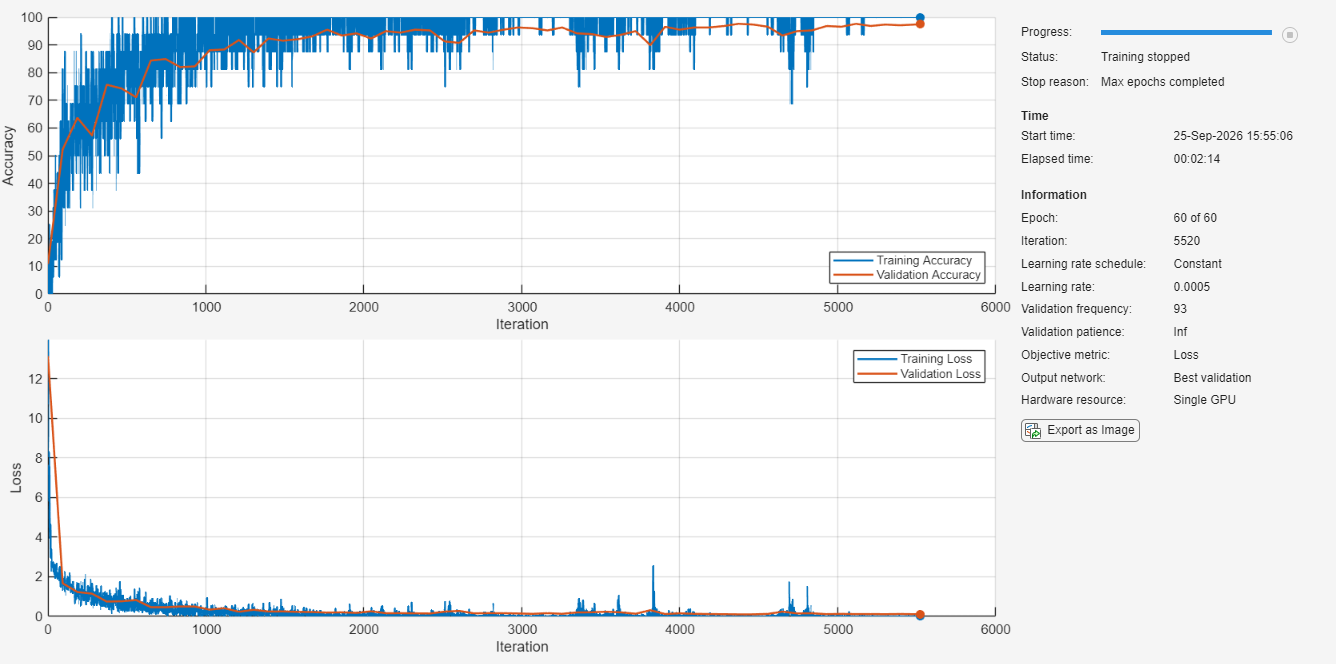

Training Lauf 1 beendet.


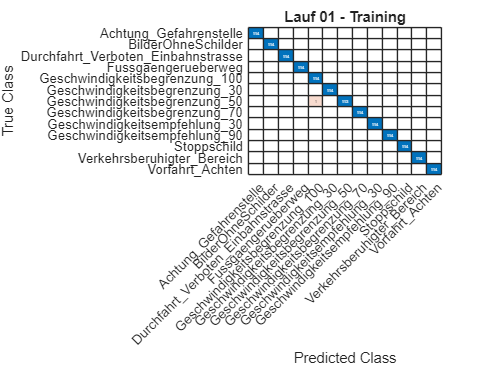

Lauf 1 - Training Accuracy: 99.93%


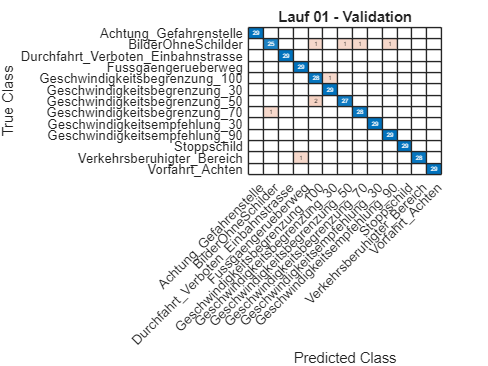

Lauf 1 - Validation Accuracy: 97.61%


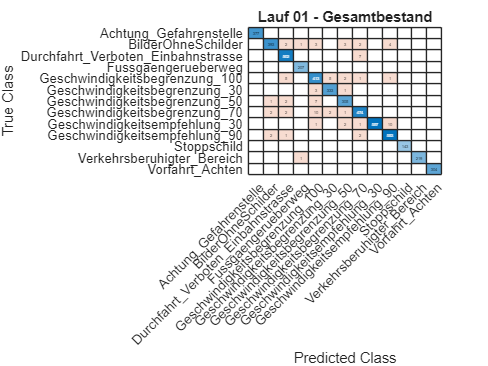

Lauf 1 - Gesamt Accuracy: 98.21%


Lauf 1 - Falsch Training: 1


Lauf 1 - Falsch Validation: 9


Lauf 1 - Falsch Gesamtbestand: 87


ENDE LAUF 1 von 1



    dateiname = imdsSchilder.Files(wrongIdxVali2);

    wrongTable = table( ...
        repmat(run, numel(wrongIdxVali2), 1), ...
        string(dateiname), ...
        string(trueLabelsVali2(wrongIdxVali2)), ...
        string(YTest2(wrongIdxVali2)), ...
        'VariableNames', ["Lauf", "Dateiname", "RichtigesLabel", "Vorhersage"]);

    writetable(wrongTable, sprintf("Falsch_Gesamtbestand_Lauf_%02d.csv", run));

    %% Werte dieses Laufs speichern
    RunNr(run) = run;
    TrainAccuracy(run) = accuracyTrain * 100;
    ValidationAccuracy(run) = accuracyVal * 100;
    GesamtAccuracy(run) = accuracyAll * 100;
    AnzahlFalschTrain(run) = numel(wrongIdxtrain);
    AnzahlFalschValidation(run) = numel(wrongIdxVali);
    AnzahlFalschGesamt(run) = numel(wrongIdxVali2);

    results = table(RunNr(1:run), ...
        TrainAccuracy(1:run), ...
        ValidationAccuracy(1:run), ...
        GesamtAccuracy(1:run), ...
        AnzahlFalschTrain(1:run), ...
        AnzahlFalschValidation(1:run), ...
        AnzahlFalschGesamt(1:run), ...
        'VariableNames', ["Lauf", "TrainingAccuracy", "ValidationAccuracy", ...
        "GesamtAccuracy", "FalschTraining", "FalschValidation", "FalschGesamt"]);

    % disp(results)

    % Nach jedem Lauf direkt schreiben, damit nichts verloren geht
    writetable(results, "GAP100_Netz2_16_KAt_13_learnErgebnisse_Einzellaeufe.csv");

    fprintf("ENDE LAUF %d von %d\n", run, numRuns);

end


fprintf("\nAlle Läufe beendet.\n");


Alle Läufe beendet.


disp(results)

    Lauf    TrainingAccuracy    ValidationAccuracy    GesamtAccuracy    FalschTraining    FalschValidation    FalschGesamt
    ____    ________________    __________________    ______________    ______________    ________________    ____________

     1           99.933               97.613              98.212              1                  9                 87     

